%[num_data, txt_data, raw_data] = xlsread('your_excel_file.xlsx');
% Specify the file name or full path to the CSV file
csvFileName = '15.csv';  % Replace with your file name or path
filename = {'15.csv','20.csv','25.csv','30.csv','35.csv','40.csv','45.csv','50.csv','60.csv','70.csv','80.csv','90.csv','100.csv','120.csv','140.csv','160.csv'};

% loop through the files opening them up and finding the average of
% positive and negative voltage values, appending them to an array 

tableVel = [15;
            20;
            25;
            30;
            35;
            40;
            45;
            50;
            60;
            70;
            80;
            90;
            100;
            120;
            140;
            160];

positiveVoltageArr = [];
negativeVoltageArr = [];

for i=1:16 
    
% Use readtable to read the CSV file
dataTable = readtable(filename{i});

% remove the first few rows from the table
dataTable = dataTable(6:end,:);
enc1_vel = table2array(dataTable(:,5));
voltage = table2array(dataTable(:,7));

positiveVoltageArr = [positiveVoltageArr, mean(voltage(voltage > 0))];
negativeVoltageArr = [negativeVoltageArr, mean(voltage(voltage < 0))];
end

% use the equation 
% sg Kt Vin = Td + B w(t) 
sg = 0.887; % A/v 
kt = 0.72; % Nm/A 
pitch = 0.02;

motor_vel = tableVel*10^-3 / pitch * 2 * pi;
Td_pos = positiveVoltageArr * sg * kt; 
Td_neg = negativeVoltageArr * sg * kt;

% Fit a linear trendline (1st-degree polynomial)
coefficients_pos = polyfit(motor_vel, Td_pos, 1);
coefficients_neg = polyfit(-motor_vel, -Td_neg, 1);

% Create a linear trendline function using the coefficients
trendline_pos = polyval(coefficients_pos, motor_vel);
trendline_neg = polyval(coefficients_neg, -motor_vel);

trend_pos = trendline_pos;
trend_neg = trendline_neg; 


% from left to right the column names are: 
% name | partA traj input | enc1 actpos | enc2 actpos | enc1 act vel | enc2
%  act vel | V sig

% convert measured table speed [mm/s] to angular velocity of motor [rad/s] 
 
% plot(angular_vel1(1:length(posVol)),Td_pos)
%  myArray = [myArray, 4];

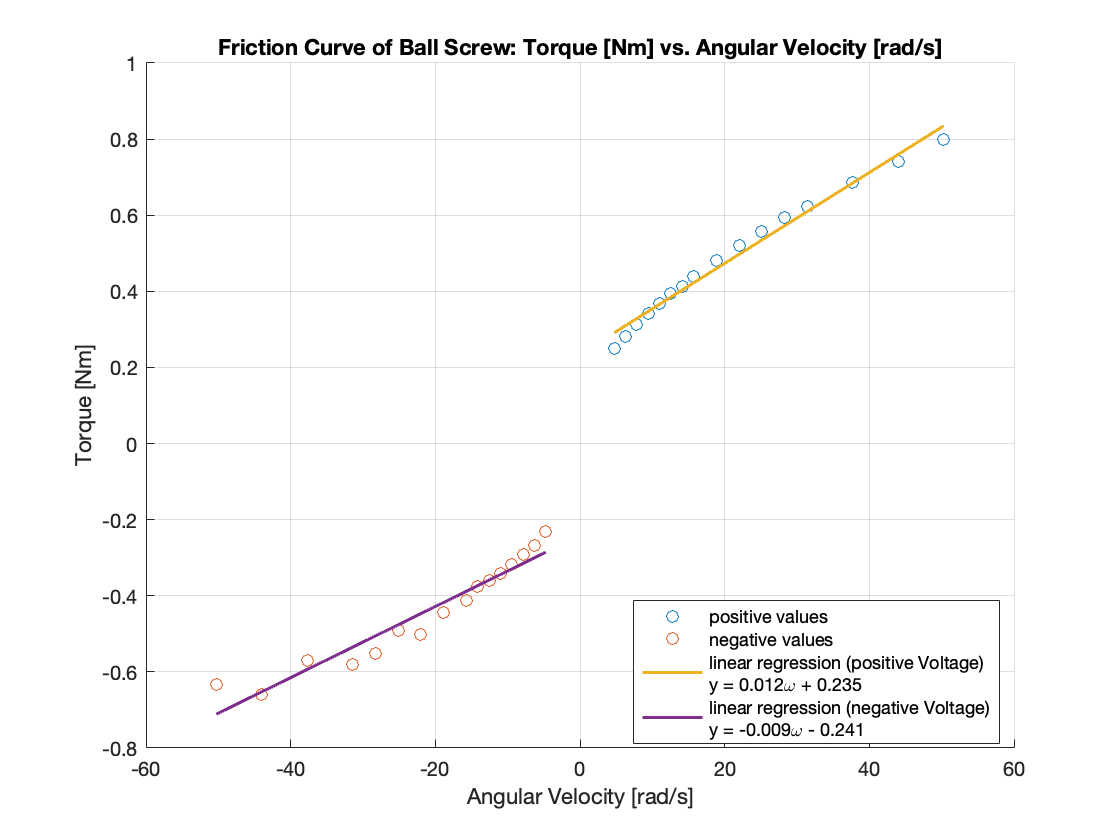


clf
hold on 
scatter(motor_vel, Td_pos);
scatter(-motor_vel, Td_neg);
plot(motor_vel, trendline_pos,linewidth=1.5);
plot(-motor_vel, -trendline_neg,linewidth=1.5);
grid on 
title('Friction Curve of Ball Screw: Torque [Nm] vs. Angular Velocity [rad/s]')
xlabel('Angular Velocity [rad/s]')
ylabel('Torque [Nm]')

trendline_label1 = ['linear regression (positive Voltage)' newline 'y = ' num2str(round(coefficients_pos(1),3)) '\omega' ' + ' num2str(round(coefficients_pos(2),3))];
trendline_label2 = ['linear regression (negative Voltage)' newline 'y = ' -num2str(round(coefficients_neg(1),3)) '\omega' ' - ' num2str(round(coefficients_neg(2),3))];

legend('positive values', 'negative values', trendline_label1, trendline_label2)

xlim('auto')

legend("Position",[0.69336,0.23122,0.18571,0.063095])

legend("Position",[0.56498,0.14003,0.32679,0.11786])

saveas(gcf, 'sectionA.png')